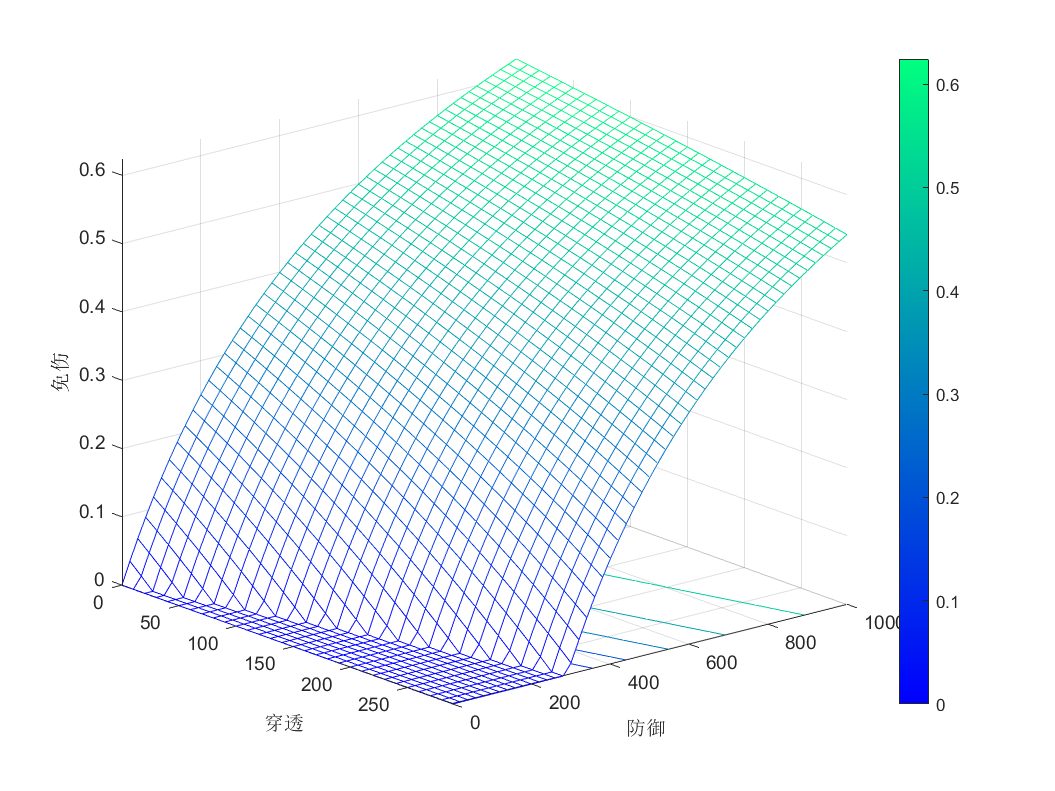

clearvars
sh.fcl = 0;
e.ms = 0;
id = 1;
maxi = 290;% 
di = 10;
maxj = 1000;% 防御
dj = 20;
for i = 0:di:maxi
    for j = 0:dj:maxj
        sh.fc = i;
        e.fk = j;
        [sh,e] = shang(sh,e,1);
        r(id,:)= [sh.fc e.fk sh.ms];
        id = id+1;
    end
end
% scatter3(r(:,1),r(:,2),r(:,3),'filled')
x = linspace(0,maxi,maxi/di+1);
y = linspace(0,maxj,maxj/dj+1);
z = r(:,3);
[X Y] = meshgrid(x,y);
Z = reshape(z,maxj/dj+1,maxi/di+1);
fig = meshc(X,Y,Z);
xlabel('穿透')
ylabel('防御')
zlabel('免伤')
colormap winter; %设置colormap的格式
colorbar; %加上色条

view([50,20]); %设置观察角度
axis([min(x) max(x) min(y) max(y)... %设置坐标范围
        min(min(Z)) max(max(Z))]); %这里由于Z是二维需要用两层最值函数
set(gcf,'Units','centimeters','Position',[6 6 20 15]); %设置图片大小